## Problem CM16 - 08/06/07

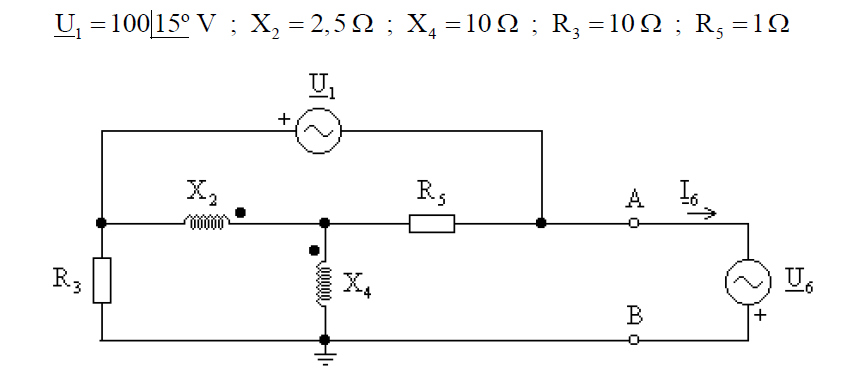

clear all
close all
clc


Matrix (A) and independent vector (B) definition Ax=B


x2=2.5

x2 = 2.5000

x4=10

x4 = 10

r3=10

r3 = 10

r5=1

r5 = 1

xm=sqrt(x2*x4)

xm = 5

u1=100*exp(1i*15*pi/180)

u1 = 96.5926 + 25.8819i


A=[1/r3, 0,0,-1,0,1;
    0,1/r5,-1/r5,1,1,0;
    0,-1/r5,1/r5,0,0,-1;
    -1,1,0,-1i*x2,-1i*xm,0;
    0,1,0,-1i*xm,-1i*x4,0;
    1,0,-1,0,0,0]

A =    0.1000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i
  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 2.5000i   0.0000 - 5.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 5.0000i   0.0000 -10.0000i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



B=[0;0;0;0;0;u1]

B =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  96.5926 +25.8819i



sol=inv(A)*B

sol = 	1.0e+02 *

  -0.7000 - 0.4898i
  -1.4000 - 0.9797i
  -1.6659 - 0.7487i
  -0.3359 + 0.1820i
   0.0700 + 0.0490i
  -0.2659 + 0.2310i


angle(sol)*180/pi

ans =  -145.0169
 -145.0169
 -155.8012
  151.5482
   34.9831
  139.0193



v1=sol(1)

v1 = -69.9993 - 48.9833i

v2=sol(2)

v2 = -1.4000e+02 - 9.7967e+01i

v3=sol(3)

v3 = -1.6659e+02 - 7.4865e+01i

ix1=sol(4)

ix1 = -33.5932 + 18.2031i

ix2=sol(5)

ix2 = 6.9999 + 4.8983i

Thevenin calculation

uth=sol(3)

uth = -1.6659e+02 - 7.4865e+01i

uthm=abs(uth)

uthm = 182.6408

utha=angle(uth)*180/pi

utha = -155.8012

z=inv(A);
zth=z(3,3)

zth = 0.8029 + 0.2920i

b section

u6=150*exp(1i*25*pi/180)

u6 = 1.3595e+02 + 6.3393e+01i

I=(uth+u6)/zth

I = -38.2993 - 0.3614i

Im=abs(I)

Im = 38.3010

Ia=angle(I)*180/pi

Ia = -179.4593

S6=-u6*conj(I)

S6 = 5.2296e+03 + 2.3788e+03i

S6=-u6*conj(I)

S6 = 5.2296e+03 + 2.3788e+03i

S6m=abs(S6)

S6m = 5.7452e+03

S6a=angle(S6)*180/pi

S6a = 24.4593

c section

I6=uth/(zth-3)

I6 = 70.0588 + 43.3850i

I6m=abs(I6)

I6m = 82.4044

I6a=angle(I6)*180/pi

I6a = 31.7685

S6=-(3*I6)*conj(I6)

S6 = -2.0371e+04